# Htrig under symmetry

## Symmetry in HR: theoritical part

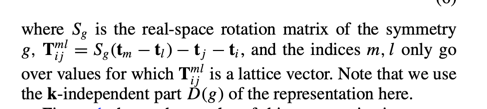

## Symmetry operation test C3

### Graphene

syms t a k_x k_y real;
bond = sqrt(3)/3 *a;
delta(1,:) = a*[1/2,-sqrt(3)/6];
delta(2,:) = a*[  0,    bond/a];
delta(3,:) = a*[-1/2,-sqrt(3)/6];
sigma_x = pauli_matric(1);
sigma_y = pauli_matric(2);
sigma_z = pauli_matric(3);
k = [k_x k_y].';
Graphene = Htrig(2);
Graphene = Graphene +...
    Trig(-t*cos(delta(1,:)*k),sigma_x)+...
    Trig( t*sin(delta(1,:)*k),sigma_y)+...
    Trig(-t*cos(delta(2,:)*k),sigma_x)+...
    Trig( t*sin(delta(2,:)*k),sigma_y)+...
    Trig(-t*cos(delta(3,:)*k),sigma_x)+...
    Trig( t*sin(delta(3,:)*k),sigma_y);
Graphene_sym = Graphene.Htrig_sym;
             Graphene_sym = simplify(rewrite(Graphene_sym,'exp'))
Graphene_exp = Graphene.rewrite();
Graphene__exp_sym = Graphene_exp.Htrig_sym

% Tr = Oper.time_reversal(2,diag([1 1]));
% Chiral = Oper.chiral(2,[1,0;0,-1]);
% sphi = sym(2/3 *pi);
C3 = Oper.rotation(2/3,nan,false,eye(2),nan,true);
% Symmetries = [ Chiral,Tr,C3];
% Graphene = Htrig(2);
% Graphene =Graphene.seeds([sym('k_x'),sym('k_y')])

Graphene_test = Graphene_exp.applyR(C3.R);
Graphene_sym1 = simplify(Graphene_test.Htrig_sym)
k = C3.R*[k_x; k_y];
simplify(subs(Graphene__exp_sym,[k_x k_y],k.'))

Graphene_test = Graphene_exp.applyU(C3.U);
Graphene_sym2 = Graphene_test.Htrig_sym
Graphene_test = Graphene_exp.applyOper(C3);
Graphene_sym = Graphene_test.Htrig_sym




## symmetry TB genreration C3

### Graphene

Graphene  = Htrig(2);
Graphene = 'POSCAR'>Graphene;
Graphene.Rm
Graphene.orbL
Graphene= Graphene.nn([1,1,0],4,1.15);
sym(Graphene.nn_store)
Graphene = Graphene.init('level_cut',1,"onsite_mode",1)
Graphene.Htrig_sym(:,1)
Graphene.HsymL_trig

C3 = Oper.rotation(2/3,nan,false,eye(2))
Tr = Oper.time_reversal(2,diag([1 1]))
Chiral = Oper.chiral(2,diag([1,-1]))

Groups = generate_group([C3,Tr,Chiral])

Graphene_test = Graphene.applyOper(Groups);

Graphene_test.Htrig_sym(:,1)

Graphene_test = Graphene.applyOper(C3)
Graphene_test = Graphene_test.applyOper(C3)
Graphene = Graphene_test.applyOper(Tr)
Graphene_test.Htrig_sym


### KaneMele